# Testing Planar Closure Approximations

To test planar closure approximations we choose a flow, calculate the tensor history by solving for the distribution function, then solve the tensor equations using the closure(s) and compare. 

Here we'll do simple shear flow, which is one of the most important tests.  You can change the flow by changing the velocity gradient tensor $\mathbf{L}$. 

First, set the parameters we'll need:

CI = 0.05; % Interaction coefficient
xi = 1;    % Particle shape factor
L  = [0, 1; 0, 0];  % Velocity gradient, simple shear
closure = 'QNF';  % Closures to test, as in closeA4planar.m
dt   = 0.1;  % Time step for results
tend = 15;   % Maximum simulation time
Co   = 0.25; % Courant number for distn. fcn.
nnod = 180;  % Grid points for distn. fcn.

% Parameters for the appearance of plots
fontsize  = 20;  % Font size, points
linewidth = 1;   % Line width, points
nplot     = 4;   % Markers every nplot points
% Line styles
lstyle    = {'-', '-.', '--', 'o', 'x', '^', 's', 'v'};

You can change the interaction coefficient or velocity gradient and compare up to 7 closure approximations by changing the lines above.

Next, solve for the full distribution function.  This is the reference result against which all closures are compared.  

% Isotropic initial condition
Azero = [0.5; 0.5; 0];
psizero = ones(nnod, 1) / (2*pi);

% Transient distribution function history
[t, ~, ~, Avdist] = solvePsi2D(L, CI, xi, tend, dt, nnod, ...
    Co, 'central', psizero);

% Steady-state distribution function
[~, ~, ~, AvSteady] = solvePsi2D(L, CI, xi, -1, dt, nnod, ...
    Co, 'central', psizero);

We've solved separately for the steady-state distribution function, since there is no guarantee that the solution at `tend` will be exactly at steady state.  

Now, cycle through the closures, solving the same problem using each closure approximation.  We'll also calculate the mean scalar error and steady-state error as we go.

% Closure solutions
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9);
Av = zeros(length(t), 3, length(closure)); % Orientation tensor results
e  = zeros(length(t), length(closure));    % Time-dependent error magnitude
emean   = zeros(1, length(closure));       % Mean error over time
esteady = zeros(1, length(closure));       % Error at final time
for i = 1:length(closure)
    % Transient solution using the closure
    [~, Av(:,:,i)] = ode45(@(t, Av) AdotPlanar(Av, L, xi, closure(i), ...
        'F', CI),   t, Azero, options);
    % Pointwise error with closure
    e(:,i) = sqrt( (Avdist(:,1) - Av(:,1,i)).^2 ...
        +(Avdist(:,3) - Av(:,3,i)).^2 );
    % Mean error over time
    emean(i) = mean(e(:,i));
    
    % Steady-state solution using the closure
    AvClosure  = AsteadyPlanar(Av(end,:,i)', L, xi, closure(i), 'F', CI);
    % Steady-state error
    esteady(i) = sqrt( (AvSteady(1) - AvClosure(1))^2 ...
        +(AvSteady(3) - AvClosure(3))^2 );
end

% Print summary results to the console:
fprintf('Closure   e_mean     e_steady\n')

Closure   e_mean     e_steady


for i = 1:length(closure)
    fprintf('   %s      %6.4f     %6.4f\n', closure(i), emean(i), esteady(i))
end

   Q      0.1316     0.1407
   N      0.0272     0.0283
   F      0.0011     0.0010


Now plot the results and have a look.  First the tensor components.

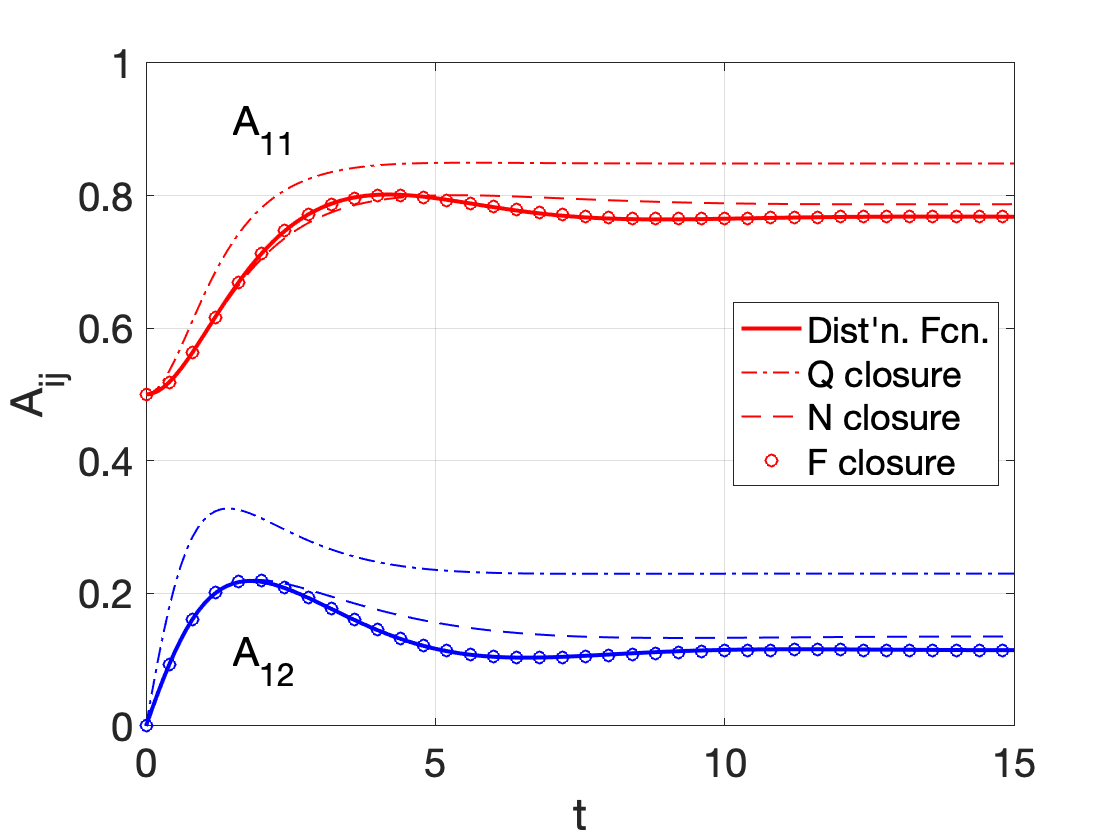

% Generate legend text for all plots
legendText = cell(1, length(closure)+1);
legendText{1} = 'Dist''n. Fcn.';
for i = 1:length(closure)
    legendText{i+1} = [closure(i), ' closure'];
end


figure(1); clf; hold on
% Plot all A11 values first, and label these w/ the legend
plot(t, Avdist(:,1), ['r', lstyle{1}], 'LineWidth', 2*linewidth)
for i = 1:length(closure)
    hl = plot(t, Av(:,1, i), ['r', lstyle{i+1}], 'LineWidth', linewidth);
    set(hl, 'MarkerIndices', 1:nplot:length(t))
end
% Then plot the A12 values
plot(t, Avdist(:,3), ['b', lstyle{1}], 'LineWidth', 2*linewidth)
for i = 1:length(closure)
    hl = plot(t, Av(:,3, i), ['b', lstyle{i+1}], 'LineWidth', linewidth);
    set(hl, 'MarkerIndices', 1:nplot:length(t))
end
set(gca, 'FontSize', fontsize)
xlabel('t')
ylabel('A_{ij}')
grid on
box on
axval = axis;
axis([0, max(t), axval(3), 1])
legend(legendText, 'Location', 'East')
text(1.5, 0.9, 'A_{11}', 'FontSize', fontsize)
text(1.5, 0.1, 'A_{12}', 'FontSize', fontsize)

Then the transient error measure.

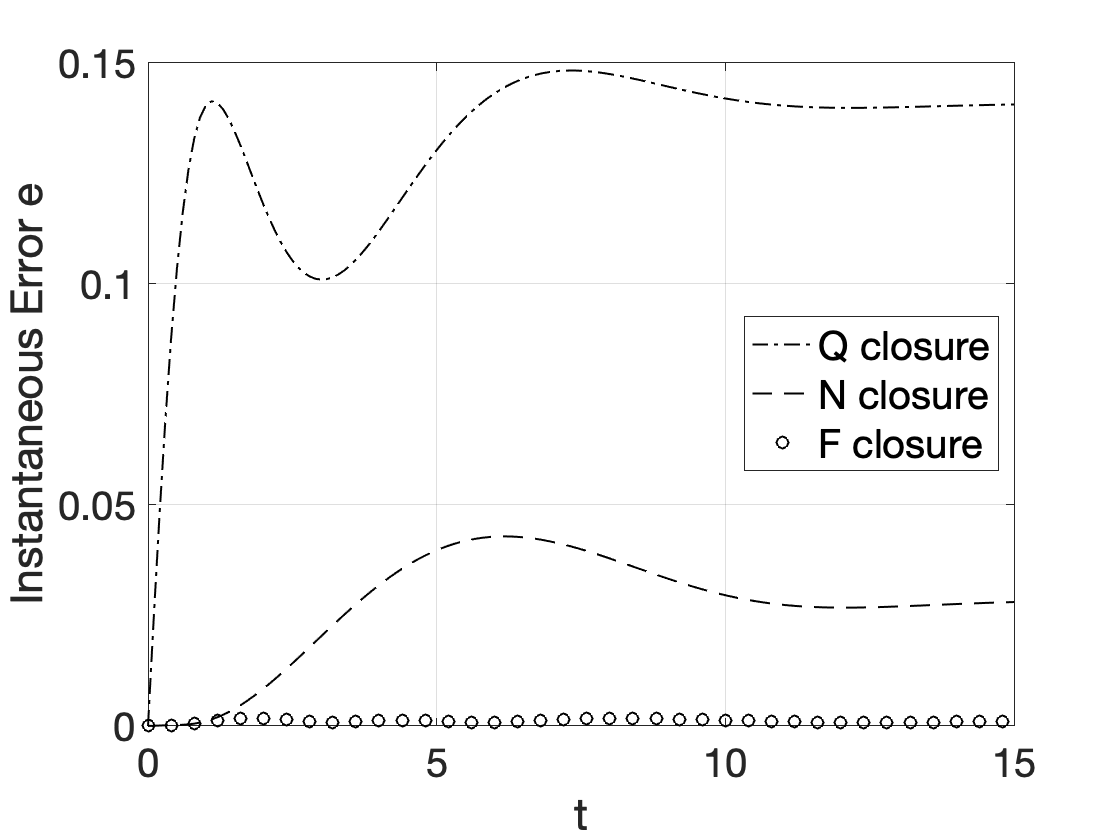

figure(2); clf; hold on
for i = 1:length(closure)
    hl = plot(t, e(:,i), ['k', lstyle{i+1}], 'LineWidth', linewidth);
    set(hl, 'MarkerIndices', 1:nplot:length(t))
end
set(gca, 'FontSize', fontsize)
xlabel('t')
ylabel('Instantaneous Error e')
grid on
box on
legend(legendText{2:end}, 'FontSize', fontsize, 'Location', 'East')